## Problem 3

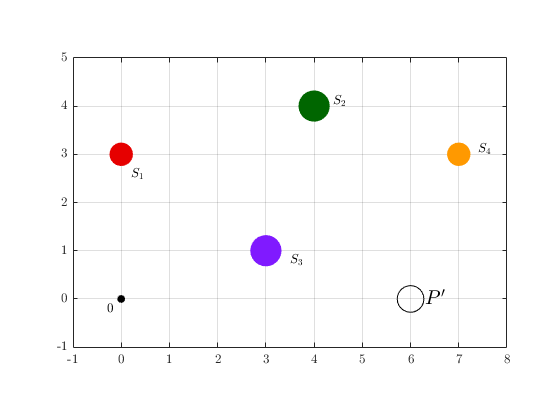

clear all; close all; clc;

fdir = 'C:\Users\Tomo\Desktop\studies\2020-Spring\AAE440\MATLAB\outputs\HW5';
set(groot, 'defaulttextinterpreter',"latex");
set(groot, 'defaultAxesTickLabelInterpreter',"latex");
set(groot, 'defaultLegendInterpreter',"latex");

% Arrow drawing function
drawArrow = @(x,y,varargin) quiver( x(1),y(1),x(2)-x(1),y(2)-y(1),0, varargin{:} );

%% (a)
% Plotting the system
% Postion vectors for each S(i) and P
d = 1;
origin = [0; 0];
S1 = [d*0 d*3];
S2 = [d*4 d*4];
S3 = [d*3 d*1];
S4 = [d*7 d*3];
P = [d*6 d*0];
S_x = [S1(1); S2(1); S3(1); S4(1)];  % all x positions 
S_y = [S1(2); S2(2); S3(2); S4(2)];  % all x positions 

name_str = ["$0$","$\hat{a}_1$","$\hat{a}_2$","$S_1$","$S_2$",...
    "$S_3$","$S_4$", "$P^\prime$"];

fig1 = figure("Renderer","painters");
hold on; grid on; box on; axis equal; 
ylim([-1, 5]); xlim([-1, 8]);
plot(origin(1),origin(2), '.','MarkerSize', 20,'Color',[0 0 0])
plot(S1(1),S1(2), '.','MarkerSize', 60,'Color',[0.9   0 0]); 
plot(S2(1),S2(2), '.','MarkerSize', 80,'Color',[  0 0.4 0]); 
plot(S3(1),S3(2), '.','MarkerSize', 80,'Color',[0.5 0.1 1]);
plot(S4(1),S4(2), '.','MarkerSize', 60,'Color',[  1 0.6 0]); 
plot(P(1),P(2), 'ko','MarkerSize',20);                     

text(-0.3, -0.2, name_str(1),"Interpreter","latex")
text(0.2, 2.6, name_str(4),"Interpreter","latex")
text(4.4, 4.1, name_str(5),"Interpreter","latex")
text(3.5, 0.8, name_str(6),"Interpreter","latex")
text(7.4, 3.1, name_str(7),"Interpreter","latex")
text(6.3, 0, name_str(8), "FontSize",15, "Interpreter","latex")

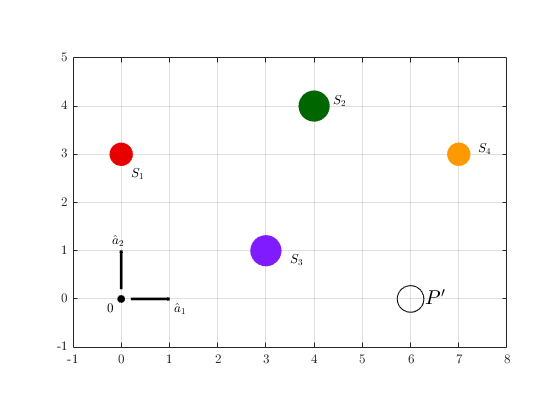

% a1_hat axis
x1 = [0.2 1]; 
y1 = [0 0]; 
drawArrow(x1,y1,'k', 'linewidth',2); text(1.1,-0.2, name_str(2),"Interpreter","latex");
% a2_hat axis
x2 = [0 0]; 
y2 = [0.2 1]; 
drawArrow(x2,y2,'k', 'linewidth',2); text(-0.2,1.2, name_str(3),"Interpreter","latex");

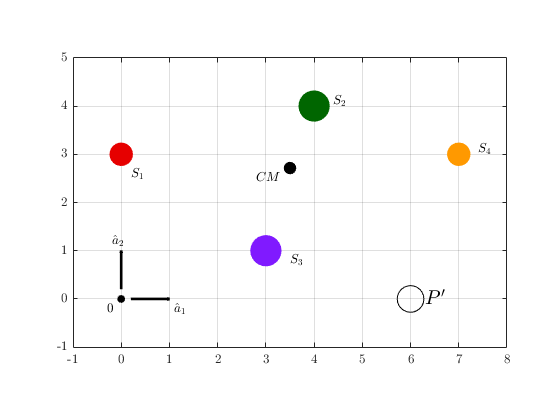

% Masses for each S(i) and P
m1 = 3; 
m2 = 4;
m3 = 4;
m4 = 3;
mP = 5;
m_S = [m1 m2 m3 m4];
m_tot = sum(m_S);

% Computing the CM of the system
x_cm = dot(S_x,m_S)/m_tot;
y_cm = dot(S_y,m_S)/m_tot;

% Plotting the CM
plot(x_cm, y_cm, '.k','MarkerSize', 32); text(2.8, 2.5, '$CM$',"Interpreter","latex");

% Re-defining positions of S(i) in terms of P' (attracting body)
S1_P = S1 - P; 
S2_P = S2 - P; 
S3_P = S3 - P; 
S4_P = S4 - P; 
S_P_all = [S1_P; S2_P; S3_P; S4_P];

% Computing the Line of action
% **Non-dimensionalized so disregard gravitational constant G
N = length(S_P_all(:,1));
dim = length(S_P_all(1,:));
F_i = zeros([N, dim]);
for i = 1:N
    F_i(i,:) = -mP.*m_S(i).*S_P_all(i,:).*norm(S_P_all(i,:)).^-3;
end
F = sum(F_i);

F =     2.1684   -3.0990


F_mag = norm(F);

F_mag = 3.7823

F_unit = F/F_mag;

F_unit =     0.5733   -0.8193


% Computing the CG
% **Non-dimensionalized so disregard gravitational constant G
R_cg = sqrt(mP*(m_tot)/norm(F));

R_cg = 4.3020

% R_cg vector is essentially G'-P' (from CG to P') vector 
% To make this into a postion vector wrt the origin we do the following vector manipulation
P_Xcg = -F*R_cg/norm(F);
O_Xcg = P + P_Xcg;

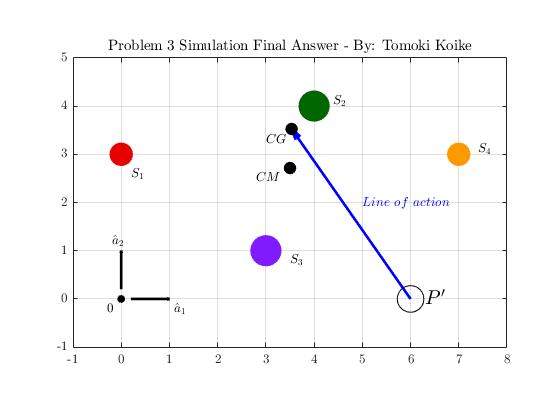

% Plotting the Line of action
x3 = [6 O_Xcg(1)];
y3 = [0 O_Xcg(2)]; 
drawArrow(x3,y3, 'linewidth',2,'Color',[0 0 1]); 
text(5, 2, '$Line$ $of$ $action$','Color','b',"Interpreter","latex");

% Plotting the CG
plot(O_Xcg(1), O_Xcg(2), 'k.','MarkerSize', 32); 
text(3, 3.3, '$CG$', "Interpreter","latex");
title('Problem 3 Simulation Final Answer - By: Tomoki Koike')
saveas(fig1, fullfile(fdir,'hw5_p3_gravity_system.png'));